# Systèmes non-linéaires et robustesse

TP1 -  Stabilité et stabilisation des systèmes

Commande distribuée d’un peloton d’automobiles

21/11 et 08/12/22

Binôme :

- Déric Augusto FRANÇA DE SALES

- Michelle FERREIRA MARTINS

Fichier généré par Matlab LiveScript v.R2020a.

## I - Modèle dynamique des véhicules


$$\frac{d^3}{dt^3} q_i = \beta_i (\dot q_i \;,\; \ddot q_i) + \alpha_i (\dot q_i) \omega_i$$


#### Q.I.1 

Le système a une ordre de trois.

#### Q.I.2

Le modèle d'état c'est toujours dans la forme:


$$Q =  
\pmatrix{ 
q_i \cr
v_i \cr
a_i
}$$
  
$$\Rightarrow$$
 
$$\dot Q =  
\pmatrix{ 
\dot q_i \cr
\dot v_i \cr
\dot a_i
} = \pmatrix{
v_i \cr
a_i \cr
\beta \;(v_i \;,\;a_i) + \alpha_i \;(v_i) \; \omega_i
}
$$


#### Q.I.3

pour déterminer la loi de commande, on va isoler $u_i$ dans le système aprés savoir qui :

$\alpha_i \; (\dot q_i) =  
\alpha_i \; (v_i) := 
\frac{1}{m_i \; \theta_i \; (\dot q_i)}$; 

$\beta_i \; (\dot q_i \;,\; \ddot q) :=
 -\frac{2 K_{di}}{m_i} \; \dot q_i \; \ddot q_i - \frac{1}{\theta_i \;(\dot q_i)} \left( \ddot q_i + \frac{K_{di}}{m_i} \; \dot q_i^2 + \frac{d_{mi}}{mi} \right)$;

$\dot a_i =
- \frac{1}{\tau} a_i + \frac{1}{\tau} u_i$.


$$\Rightarrow   

-\frac{2 K_{di}}{m_i} \; \dot q_i \; \ddot q_i - \frac{1}{\theta_i \;(\dot q_i)} \left( \ddot q_i + \frac{K_{di}}{m_i} \; \dot q_i^2 + \frac{d_{mi}}{mi} \right)

+ \frac{1}{m_i \; \theta_i \; (\dot q_i)} \cdot \omega_i
=
- \frac{1}{\tau} a_i + \frac{1}{\tau} u_i$$



$$\Rightarrow 
\omega_i =
 \left( 
- \frac{1}{\tau} a_i + \frac{1}{\tau} u_i

+\frac{2 K_{di}}{m_i} \; \dot q_i \; \ddot q_i + \frac{1}{\theta_i \;(\dot q_i)} \left( \ddot q_i + \frac{K_{di}}{m_i} \; \dot q_i^2 + \frac{d_{mi}}{mi} \right)
\right) 

\cdot \left(
m_i \; \theta_i \; (\dot q_i)
\right)$$



$$\Rightarrow 
\omega_i =
 \left( 
- \frac{1}{\tau} a_i + \frac{1}{\tau} u_i

+\frac{2 K_{di}}{m_i} \; v_i \; a_i + \frac{1}{\theta_i \;(v_i)} \left( a_i + \frac{K_{di}}{m_i} \; v_i^2 + \frac{d_{mi}}{mi} \right)
\right) 

\cdot \left(
m_i \; \theta_i \; v_i
\right)$$


Alors, avec ça, on peut obtenir la répresentation d'état linearisé plus simple :


$$\dot Q =  
\pmatrix{ 
\dot q_i \cr
\dot v_i \cr
\dot a_i
} = \pmatrix{
v_i \cr
a_i \cr
- \frac{1}{\tau} a_i + \frac{1}{\tau} u_i
}
$$


#### Q.I.4

En regime permanent on va avoir qui $\dot a_i$ = 0, depuis que les variables de la équation de premier degrée seront linéaires. Ensuite, quand $\dot a_i$ = 0 on va avor $a_i = u_i$, donc on peut légitimement appeller $u_i$ l'accélération désirée du véhicule i. 

## II - Objectifs et lois de commande

#### Q.II.1

On a que "r" c'est la distance sécurisé entre deux vehicules et "h" le temps inter-vehicule désiré. Alors en régime pérmanent, la vitesse va être constant e $d_{r,i} = r + hc$  (constant). Si dans cet moment oú les variables se devient constants et elles permanecent constants en $t \rightarrow \infty$(vrai régime permanent), on va avoir que $d_i = d_{r, i}$ $\forall i$, si $e_i = 0$ pour $t \rightarrow \infty$.

Si on reste dans la distance désiré en regime permanent, on ne vas pas avoir des colisions entre les voitures. Alors ça c'est notre but.

#### Q.II.2

Un controleur de retour d'état de sortie dynamique, depuis que il travail avec une dérivée (alors il n'est pas statique) et avec la sortie du système.

#### Q.II.3

L'expression consiste en une partie qui multiplie l'erreur par un gain proportionnel et une partie qui multiplie l'erreur par un gain différentiel. A la fin, l'accélération est ajoutée. En pratique, sa mise en œuvre agit à la fois dans le régime transitoire et permanent, améliorant la stabilité du système.

## III - Analyse et réglagle des lois de commande

#### Q.III.1

clc; clear all; close all;

% valeurs numériques de la table 1 :
tau = 0.1;
h = 0.6;
L = 3;
r = 2.5;
rho = 0.04;
Kp = 0.2;
Kd = 0.7;

% eqs (11) :

A2 = [-(1/tau), 0, 0, 0, 0
      0, 0, 1, -h, 0
      1, 0, 0, -1, 0
      0, 0, 0, -(1/tau), (1/tau)
      0, (Kp/h), (Kd/h), -Kd, -(1/h)];
  
A3 = [-(1/tau), (1/tau), 0, 0, 0, 0
        0, -(1/h), 0, 0, 0, 0
        0, 0, 0, 1, -h, 0
        1, 0, 0, 0, -1, 0
        0, 0, 0, 0, -(1/tau), (1/tau)
        0, 0, (Kp/h), (Kd/h), -Kd, -(1/h)]

A3 =   -10.0000   10.0000         0         0         0         0
         0   -1.6667         0         0         0         0
         0         0         0    1.0000   -0.6000         0
    1.0000         0         0         0   -1.0000         0
         0         0         0         0  -10.0000   10.0000
         0         0    0.3333    1.1667   -0.7000   -1.6667


eig(A2)

ans =   -9.2680 + 0.0000i
  -1.6667 + 0.0000i
  -0.3660 + 0.2861i
  -0.3660 - 0.2861i
 -10.0000 + 0.0000i


eig(A3) % autovalor

ans =   -9.2680 + 0.0000i
  -0.3660 + 0.2861i
  -0.3660 - 0.2861i
  -1.6667 + 0.0000i
 -10.0000 + 0.0000i
  -1.6667 + 0.0000i


Une matrice carrée A est appelée matrice de Routh-Hurwitz (de stabilité) si toutes les valeurs propres de A ont une partie réelle strictement négative. Puis, étant donné les valeurs du tableau 1, les matrices A1 et A2 sont des matrices de Hurwitz. Ainsi, le système sera stable, présentant une rétroaction négative.

Puisque les matrices A sont de Routh-Hurwitz, le système est dit stable et il y a une garantie d'un point d'équilibre (dans la rélation 10).  Si $z_i = 0$, tous les éléments de $z_i$ doivent être nuls (rélation 9), y compris $e_i$, donc il y aura nécessairement une stabilité. Dans le cas où ei est nul, la distance entre les véhicules sera égale à la distance souhaitée (rélation 5) et donc le premier objectif sera atteint, garantissant la stabilité individuelle.

$e_i := d_i - d_{r,i}$   (5)

$z_2 := (a_1, e_2, v_1 - v_2, a_2, u_2)^T \\
z_i := (a_{i-1}, u_{i-1}, e_i, v_{i-1} -v_{i}, a_i, u_i)^T$   (9)

$\dot z_2 := \left( A_2 \cdot z_2 \right) + \left( B\cdot u_{1} \right) \\
\dot z_1 := \left( A_{>2} \cdot z_i \right) + \left( B _{>2} \cdot X_{i-1} \right)$    (10)

### **III.2 - Phénomène d'acordéon**

#### **Q.III.2**

Si on a que $X_2 = C_2 z_2 + u_1$ et $X_i = C_{>2} z_i$ in $i \in \{ 3, ..., N \}$. Avec les relations 8 et 9, on a :


$$K_p e_i + k_d \dot e_i + u_{u-1}

=

C_{>2} \cdot  (a_{i-1}, u_{i-1}, e_i, v_{i-1} -v_{i}, a_i, u_i)^T$$



$$\Rightarrow C_{>2} = \frac{K_p e_i + k_d \dot e_i + u_{u-1}}{  (a_{i-1}, u_{i-1}, e_i, v_{i-1} -v_{i}, a_i, u_i)^T}

; i \in \{ 3,...,N\}
$$


et  $K_p e_2 + k_d \dot e_2 + u_{u-1}

=

C_{2} \cdot (a_1, e_2, v_1 - v_2, a_2, u_2)^T$


$$\Rightarrow C_2 = \frac{K_p e_2 + k_d \dot e_2 + u_{u-1}}{(a_1, e_2, v_1 - v_2, a_2, u_2)^T}
$$


#### Q.III.3

En vérifiant la stabilité $\mathcal{L}_2$ par la méthode de Von Neumann, on constate que le côté droit de l'équation (13) doit être inférieur ou égal au côté gauche. Pour garantir cela, étant donné une entrée  $\chi_i$, $z_i$ doit être suffisamment petit pour maintenir l'inégalité. Plus $z_i$ est petit, plus ei sera petit, c'est-à-dire plus la différence entre la distance souhaitée et la distance réelle sera faible.

## **IV - Simulations**

Pour la simulation du système, le logiciel Simulink a été utilisé, qui fonctionne avec Matlab. Les constantes qui sont utilisées dans Simulink Simulation sont définies ci-dessous.

clc; clear all; close all;

% valeurs numériques de la table 1 :
tau = 0.1;
h = 0.6;
L = 3;
r = 2.5;
rho = 0.04;
kp = 0.2;
kd = 0.7;
N = 3;

#### **Q.IV.1**

Ainsi, dans la simulation, la courbe d'accélération du premier véhicule a été générée par le biais du diagramme ci-dessous, obtenant comme sortie le graphique présenté ci-dessous.

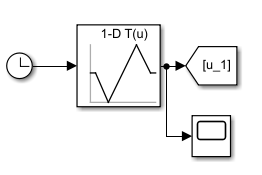

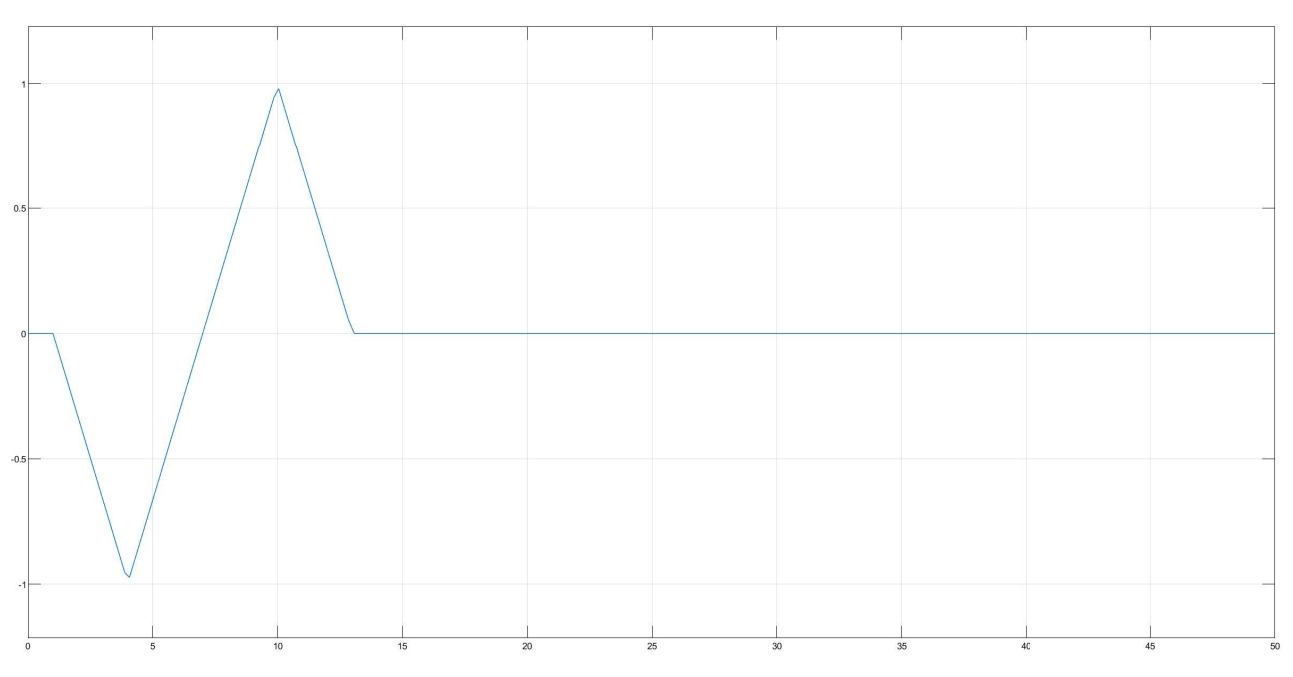

Selon la courbe, on peut voir que le premier véhicule du peloton va freiner, présentant d'abord une accélération négative, puis accélérer et décélérer jusqu'à rétablir une vitesse constante (accélération nulle). Ainsi, les autres relations ont été définies par les diagrammes ci-dessous :

 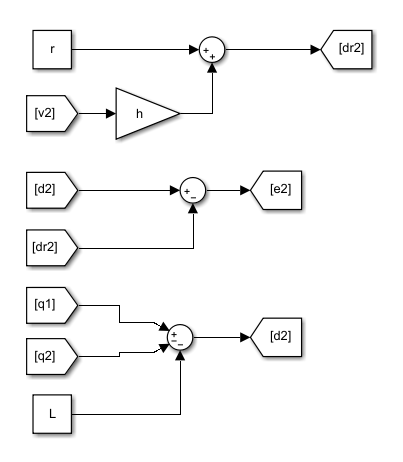

$d_{r,i} = r + h v_i$   (3) 

$d_i = q_{i-1} - q_{i} - L$ (4)

$e_i := d_i - d_{r,i}$  (5)

Où, dans la relation (3), $d$ est la distance entre le véhicule $i$ et le véhicule $i-1$, $r$ étant la distance de sécurité et $h$ le temps inter-véhicule désiré. Dans la relation (4), $q$ est la position du véhicule et $L$ est la longueur de chaque véhicule. Et enfin, dans la relation (5) $e_i$ est  l’écart entre la distance désirée entre les véhicules $i-1$ et $i$, et la distance réelle.  Le diagramme ci-dessous représente également la relation (8) décrite dans le script de la leçon pratique.

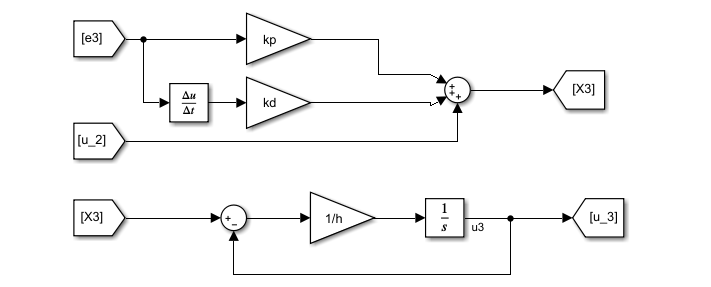

Ainsi, nous pouvons modéliser la relation (2) décrite dans le script, qui définit la position de chaque véhicule.

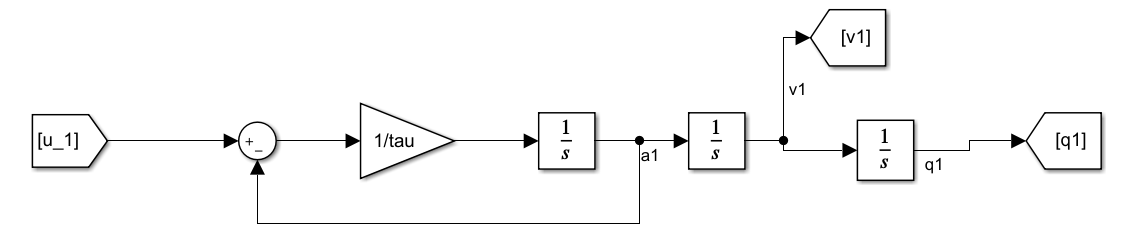

En modélisant enfin trois véhicules, selon les schémas décrits ci-dessus, on obtient alors les courbes des vitesses des trois véhicules.

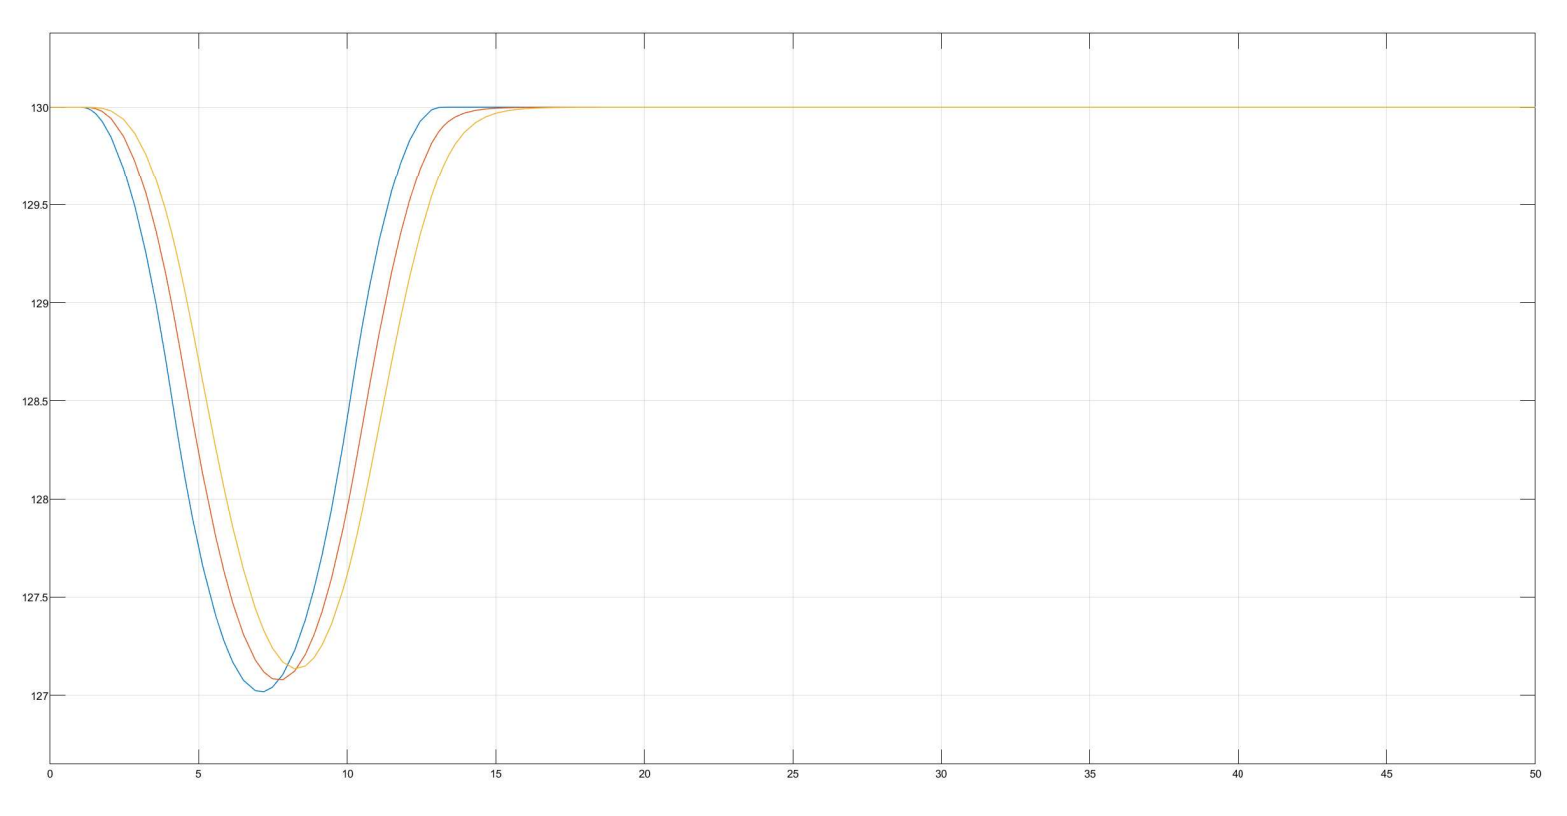

On peut voir que lorsque le premier véhicule réduit sa vitesse de 130 km/h à 127 km/h (courbe bleue), les deux autres véhicules réduisent également leur vitesse en cascade.

Il est évident que cela se produit afin que les véhicules arrière ne percutent pas le véhicule avant. Il est toutefois intéressant de noter que le véhicule le plus en arrière dans la file d'attente (dont la courbe de vitesse est jaune) a une réduction de vitesse plus faible que le véhicule qui le précède (courbe de vitesse orange). 

Ceci est dû à la distance de sécurité, qui permet de l'envahir lors de la décélération en la lissant. Il n'est pas nécessaire de décélérer aussi fortement que le véhicule qui précède. 

Si l'on extrapole l'expérience avec un plus grand nombre de véhicules, ou même si l'on augmente la distance de sécurité, l'un des véhicules les plus en arrière dans la file n'aura même pas besoin de décélérer lorsque le premier de la file décélérera. 

Cela démontre l'efficacité du système de contrôle et son bon fonctionnement, lorsque les véhicules connaissent la vitesse du véhicule qui les précède.

#### **Q.IV.2**

Après avoir effectué la première simulation, une deuxième simulation a été réalisée en supprimant le terme de la relation (8) qui donne l'information de la vitesse de la voiture devant à la voiture derrière :

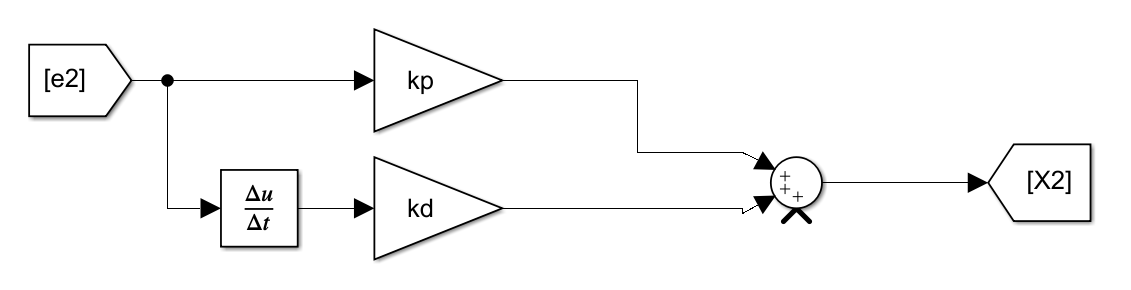

Le résultat de cette relation est le graphique ci-dessous. Contrairement au premier graphique présenté, le graphique ci-dessous montre que sans information sur la vitesse de la voiture qui précède, les voitures derrière doivent freiner de plus en plus. Si nous extrapolons l'expérience en augmentant le nombre de voitures, nous obtiendrons que la dernière voiture de la rangée présente une décélération instantanée, avec une réduction de vitesse infinie. Cela démontre l'importance de ces données dans le système de contrôle.

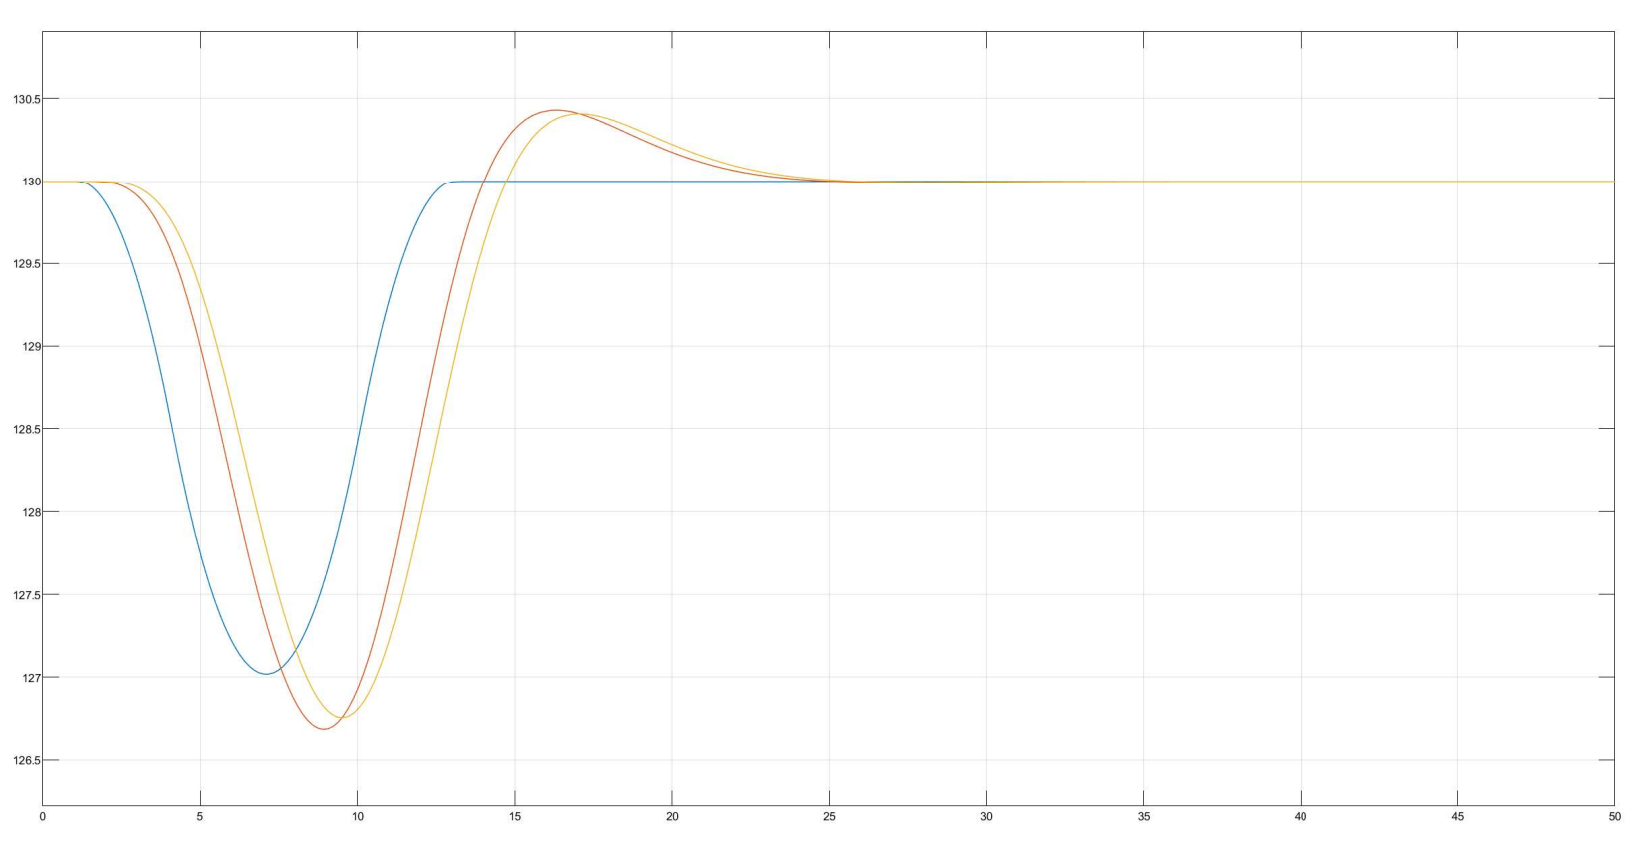

Nous avons ainsi obtenu les comportements du système de contrôle en simulant différentes situations et relations.